# Wave Equation - PDE (Finite difference method)

% Options
sympref('AbbreviateOutput', false);
N = 100; % number of states when finite differencing

% Parameters of wave equation
params = struct;
vecs = struct;   % for vector parameters
params.c = 30;           % speed

% initial condition - NB: should be vector of size N:
vecs.h = zeros(N, 1);
vecs.h(1:10) = 0.1:0.1:1;
vecs.h(11:20) = 0.9:-0.1:0;
vecs.dh = zeros(N, 1);
vecs.y0 = [vecs.h; vecs.dh];
% vecs.y0 = vecs.y0(:);

% Parameters
syms c;

% coordinates
syms x;
syms t;

% symfuns
syms y(x,t);

## Model building, to get equations of motion

First build the PDE, then create a finite difference approximation

% Wave equation with speed 'c', no dispersion
PDE = diff(diff(y, t), t) == c^2 * diff(diff(y, x), x)

$$PDE(x, t) = \frac{\partial^{2}}{\partial t^{2}}y\left(x,t\right)=c^{2}\,\frac{\partial^{2}}{\partial x^{2}}y\left(x,t\right)$$


% Finite difference approximation vector for the 'x' variation (not 't')
syms Y(t) Y_dot(t)

% Define linear operators (matrices) for derivatives using central differences
syms D D2

% Construct ODE for finite difference approximation
ODE = subs(PDE, {diff(diff(y, t), t), diff(diff(y, x), x), diff(y,t), diff(y, x), y}, ...
    {diff(diff(Y,t),t), D2*Y, diff(Y,t), D*Y,  Y,})

$$ODE(x, t) = \frac{\partial^{2}}{\partial t^{2}}Y\left(t\right)=D_{2}\,c^{2}\,Y\left(t\right)$$

## Numerical solution of equations of motion

We can also find numerical solutions to the EOM by using Matlab's IVP solvers like ode45. We must first convert the equations to first order:

% Numerical solution using ode45
% Yf = formula(Y);
[SSeq,S] = stateSpaceEquations(ODE,{Y});

Reformulating equations to nonlinear state-space form, this may take a while!


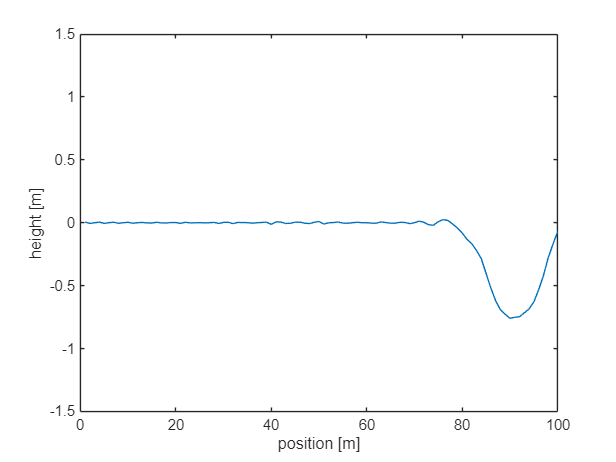


% Code generate a function to evaluate the RHS of these first order ODEs
F = subs(SSeq, params);
Y = S(1); Y_dot = S(2);
% f_ode = matlabFunction(F,'vars',{t,Y,Y_dot,D,D2});
f_ode = eval(['@(t,Y,Y_dot,D,D2)', char(F)]);   % to avoid matlabFunction being too clever and changing * to .* :-)

% Now introduce the needed differencing operators

% Order 2 central differences:
% D = 0.5*diag(ones(N-1,1),1) - 0.5*diag(ones(N-1,1),-1);  % First derivative 
% D2 = diag(ones(N-1,1),1) - 2*diag(ones(N,1)) + diag(ones(N-1,1),-1); % Second derivative

% Order 4 central differences:
D = 1/12*diag(ones(N-2,1),-2) - 2/3*diag(ones(N-1,1),-1) + 2/3*diag(ones(N-1,1),1) - 1/12*diag(ones(N-2,1),2);  % First derivative 
D2 = -1/12*diag(ones(N-2,1),-2) + 4/3*diag(ones(N-1,1),-1) - 5/2*diag(ones(N,1)) + 4/3*diag(ones(N-1,1),1) - 1/12*diag(ones(N-2,1),2);  % First derivative 

% function handle for simulation using these finite differences
f = @(t,s) f_ode(t, s(1:N), s(N+1:2*N), D, D2);

% Numerical solution using ode45
opts = odeset;
opts.MaxStep = 0.1;
odesol = ode45(f, [0,10], vecs.y0, opts);
% odesol = ode45(f, [0,10], vecs.h, opts);

tt = odesol.x;
yy = odesol.y(1:N,:);
vv = odesol.y(N+1:2*N,:);

% Visualise motion of system 
fig = figure(1);
plot(yy(:,1));
axis manual
ylim([-1.5,1.5]);
xlabel('position [m]'); ylabel('height [m]');
yy_line = fig.Children.Children;
drawnow;
tlast = datetime;
% render at (max) 60fps
for k=3:2:length(tt)        % show every other frame
    yy_line.YData = yy(:,k);
    tnow = datetime;
    pause(1/60 - seconds(tnow-tlast));
    tlast = tnow;
    drawnow;
    % frm(k) = getframe(gcf);
end

## Get mass and stiffness matrices for the system

In this part, we express the equations of motion in the (linearised) second order matrix form $M\ddot{x}+C\dot{x}+Kx=G$

% % We will linearise around the equilibrium point
% x_lin = eq_point;
% v_lin = zeros(N,1);
% 
% % M is Jacobian w.r.t. the accelerations, evaluated at equilibrium point
% M = -jacobian(eom_vars, a);
% M = subs(M, [x,v], [x_lin, v_lin])
% % C is Jacobian w.r.t. velocities, evaluated at linearisation point
% C = -jacobian(eom_vars, v);
% C = subs(C, [x,v], [x_lin, v_lin])
% % K is the Jacobian w.r.t. positions, at linearisation point
% K = -jacobian(eom_vars, x);
% K = subs(K, [x,v], [x_lin, v_lin])
% % Weight vector G is the constants, but the easiest way to get them is:
% G = simplify(diff(eom_vars,g))*g

## Code Generate a simulink model to simulate the (linearised) system

% % Form the right-hand side of the linearised (really, affine due to G!) system ODEs in state-space form
% ode_rhs = [M_uf \ (G_uf - C_uf*v - K_uf*x);  v];
% S = [v; x];
% IC = strcat('zeros(', num2str(2*N) ,',1)');      % zero initial conditions 
% 
% % Generate simulink model
% openLoopModel(ode_rhs, S, [], IC, 'cantilever');